%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TempleNoisyclip1_Agra.wav');

player = audioplayer(samples, fsample);
play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel

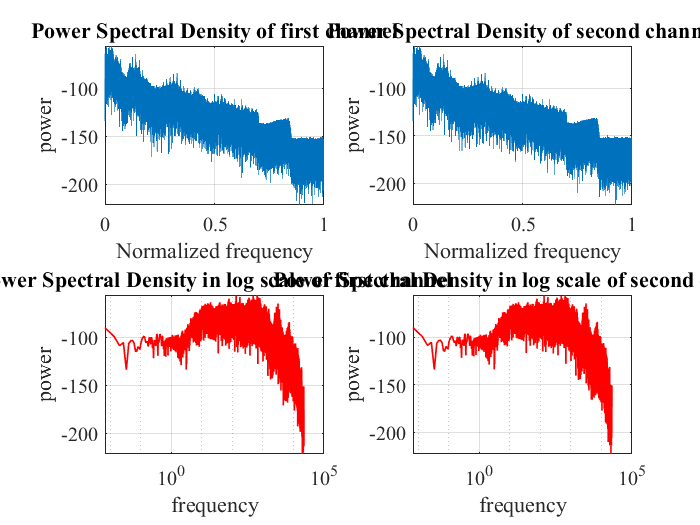

% PSD Show

ShowPSD(samples, fsample);

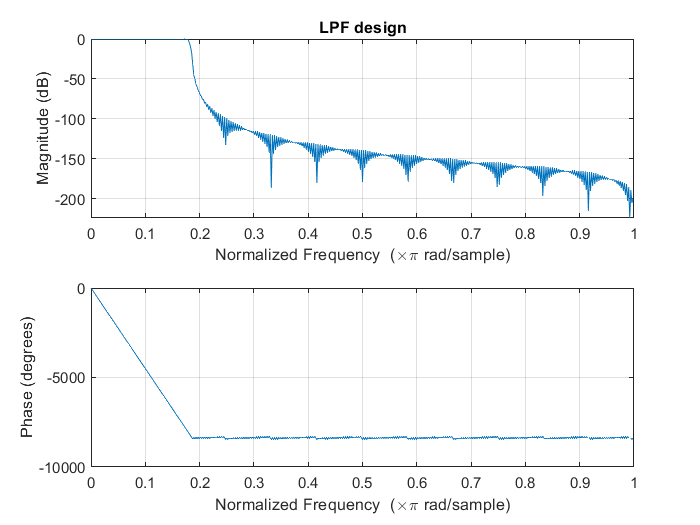

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




player = audioplayer(NewSample, fsample);
play(player);


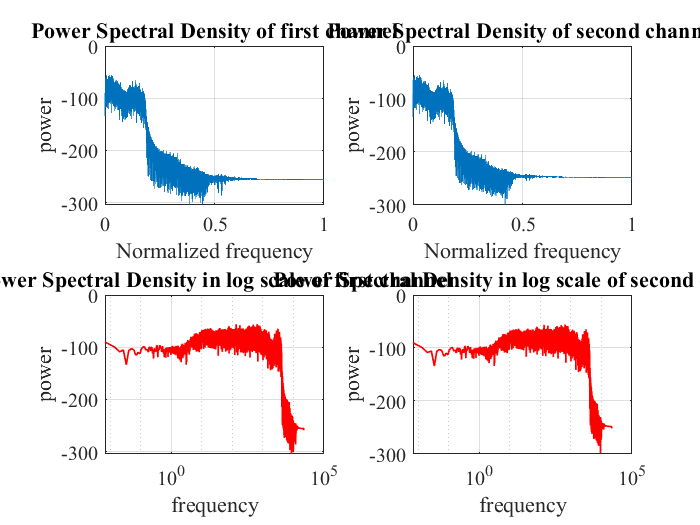

% PSD view
ShowPSD(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


Data = [1, 1, 2, 3, 4, 3, 2, 1, 4, 5, 6, 7, 8, 9, 12, 3, 4, 4, 5, 6, 6, 7, 8, 10]

Data =      1     1     2     3     4     3     2     1     4     5     6     7     8     9    12     3     4     4     5     6     6     7     8    10
